# **Import pretrained YOLOv3 network from the Darknet Framework **

This example shows how to import pretrained YOLOv3 network from Darknet and how to assemble it. This mlx is a revised version of tb_darknet2ml.mlx of the [Darknet Importer ](https://www.mathworks.com/matlabcentral/fileexchange/71277-deep-learning-darknet-importer)specialized for importing YOLOv3 network. 

[Japanese] 本例題ではDarknet上で学習されたYOLOv3をMATLABにインポートし、検出するまでの流れをご紹介します。このスクリプトはDarknet Importer内のtb_darknet2ml.mlxをYOLOv3をインポートするために書き直したものです。

clear all, close all, clc;

## Download and unzip the Darknet Importer from FileExchange.

work_dir = ['src', filesep, 'YOLOv3', filesep];
if ~exist([work_dir, 'importDarknet_v1p2'], 'dir')
    websave([work_dir, 'darkNetImporter.zip'], ...
        'https://www.mathworks.com/matlabcentral/mlc-downloads/downloads/e317e446-9671-4613-bcfc-42971ff6fb3e/09ea94c8-7886-4e85-9365-71800af40a02/packages/zip');
    unzip([work_dir, 'darkNetImporter.zip'], ...
        work_dir);
    addpath([work_dir, 'importDarknet_v1p2']);
end

## Setup

Darknet Importer uses zero padding layer and global average pooling layer that are provided by Keras Importer. To get Keras Importer, 

install [Deep Learning Toolbox™ Importer for TensorFlow-Keras Models](https://jp.mathworks.com/matlabcentral/fileexchange/64649-deep-learning-toolbox-importer-for-tensorflow-keras-models).

[Japanese] Darknet Importerはzero padding layerやglobal average pooling layer等のKeras Importerで提供されるレイヤを使用します。

予め [Deep Learning Toolbox™ Importer for TensorFlow-Keras Models](https://jp.mathworks.com/matlabcentral/fileexchange/64649-deep-learning-toolbox-importer-for-tensorflow-keras-models) のインストールをお願い致します。

## Download Pretrained Network

In this example, you can generate pretrained YOLOv3 320x320, YOLOv3 416x416, and YOLOv3 608x608 networks. These models are generated from a common model.

[Japanese] 本例題ではYOLOv3 320x320, YOLOv3 416x416, and YOLOv3 608x608を作成できます。これらの元となるモデルは共通です。

% download 
cfgfile = 'yolov3.cfg';
if ~exist(cfgfile,'file')
    websave([work_dir, cfgfile], ['https://github.com/pjreddie/darknet/raw/master/cfg/', cfgfile]);
end

weightsfile = 'yolov3.weights';
if ~exist(weightsfile,'file')
    websave([work_dir, weightsfile], ['https://pjreddie.com/media/files/', weightsfile]);
end

## Import a Pretrained Network Using Importer

Create layerGraph object from downloaded cfg file and weights file

[Japanese]importerを利用してダウンロードしたcfgファイルとweightsファイルからlayerGraphオブジェクトに変換します

[lgraph, anchors, numclasses] = importDarknetNetwork(weightsfile, cfgfile);

Darknet weights file version info
Major : 0 Minor : 2 Revision : 0
Loading cfg file
Creating graph of network layers for deep learing
--------------------------------------------------------------------
Image input layer : Height - 608 Width - 608 Channel - 3
2D conv layer 1 : Filtersize - 32 : Stride - 1 : Read param# - 864
Batch norm layer 1 : Read param# - 128
ReLU layer 1 : Scale - 0.1
Zero padding layer : Padding size - 1  0  1  0
2D conv layer 2 : Filtersize - 64 : Stride - 2 : Read param# - 18432
Batch norm layer 2 : Read param# - 256
ReLU layer 2 : Scale - 0.1
2D conv layer 3 : Filtersize - 32 : Stride - 1 : Read param# - 2048
Batch norm layer 3 : Read param# - 128
ReLU layer 3 : Scale - 0.1
2D conv layer 4 : Filtersize - 64 : Stride - 1 : Read param# - 18432
Batch norm layer 4 : Read param# - 256
ReLU layer 4 : Scale - 0.1
Addition layer (shortcut) 1
Zero padding layer : Padding size - 1  0  1  0
2D conv layer 5 : Filtersize - 128 : Stride - 2 : Read param# - 73728
Batch norm 

## Plot Neural Network Layer Graph

Visualize imported network architecture using plot method 

[Japanese]取り込んだlayerGraphを可視化し、ネットワークアーキテクチャを確認します

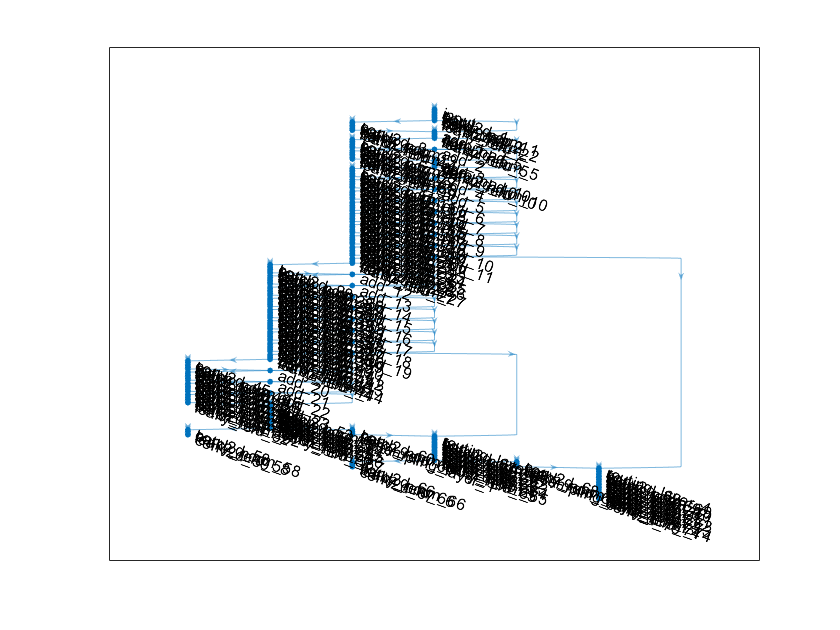

figure,
plot(lgraph)

%analyzeNetwork(lgraph);

## Convert a Layer Graph to a Network Ready for Object Detection

The iimported layergraph needs finalization. The 3 outputs layer is concatenated in depth dimension by depthConcatenationLayer. Then, the concatenated map is converted into the single output by regressionLayer.

[Japanese] 作成したlayerGraphオブジェクトを完成させます。3つの出力レイヤがあるので、それらをdepthConcatenationLayerで統合して、regressionLayerでDAG Networkとします。

inputImSize = 416; % available 320, 416, or 608 
yolov3net = finalizeImportedYOLOv3Lgraph(lgraph, inputImSize);

this =   ZeroPadding4YOLOv3Layer のプロパティ:

       Name: 'zero_padding2d_l1'
    Amounts: 4
        Top: []
     Bottom: []
       Left: []
      Right: []

  すべてのプロパティを表示


this =   ZeroPadding4YOLOv3Layer のプロパティ:

       Name: 'zero_padding2d_l2'
    Amounts: 2
        Top: []
     Bottom: []
       Left: []
      Right: []

  すべてのプロパティを表示


savename = sprintf('%syolov3-%d.mat', work_dir, inputImSize);
save(savename, "yolov3net");

## Test the generated network

Read an image and test the netwok using it.

[Japanese]画像を読み込んで検出できるかテストしてみます。

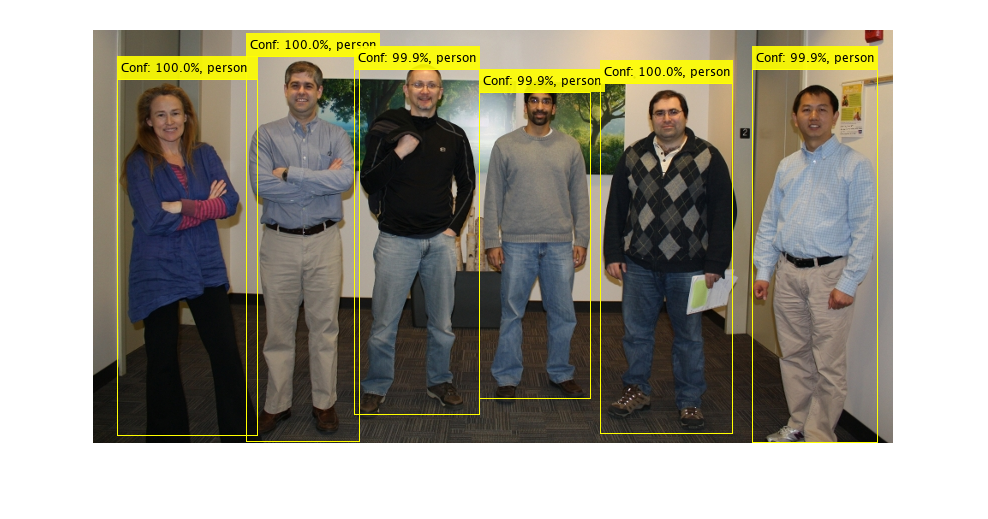

img = imread('visionteam.jpg');
[I,bboxes,scores,labels] = detect_w_PretrainedYOLOv3(img, yolov3net);
imshow(I);

## Reference

[1] Redmon, J. and A. Farhadi. "YOLO9000: Better, Faster, Stronger." IEEE Conference on Computer Vision and Pattern Recognition (CVPR), 6517–6525. Honolulu, HI: CVPR 2017.

[2] Redmon, J., S. Divvala, R. Girshick, and A. Farhadi. "You only look once: Unified, real-time object detection." *Proceedings of the IEEE Conference on Computer Vision and Pattern Recognition (CVPR), 779–788*. Las Vegas, NV: CVPR, 2016.

[3] Redmon, J. and A. Farhadi. "YOLOv3: An Incremental Improvement."

## Citation

Darknet : Open Source Neural Networks in C

%Citing
% @misc{darknet13,
%   author =   {Joseph Redmon},
%   title =    {Darknet: Open Source Neural Networks in C},
%   howpublished = {\url{http://pjreddie.com/darknet/}},
%   year = {2013--2016}
% }

*Copyright 2020 The MathWorks, Inc.*